location = 'D:\Elastic2D_Propagation\dataVoidDetection\data 200x200';
Imds = imageDatastore(location,'IncludeSubFolders',true,'FileExtensions', ...
    '.png','LabelSource','foldernames');
summary(Imds.Labels)

     Crack        140 
     NoCrack      145 


Split the data into training and hold-out test sets, with 70 percent of the images in the training set and 30 percent in the test set. Set the random number generator for reproducibility.

rng(10); % Set random seed for reproducibility
Imds = shuffle(Imds); % Shuffle the dataset

% Split into train, validation, and test sets
[trainImds, testImds] = splitEachLabel(Imds, 0.7);  % 70% for training
% [validImds, testImds] = splitEachLabel(remainingImds, 0.6); % 60% of remaining for validation, 40% for testing

Verify that equal numbers of each parasite class are contained in both the training and test sets.

summary(trainImds.Labels)

     Crack         98 
     NoCrack      102 


% Perform the same for the test set.
summary(testImds.Labels)

     Crack        42 
     NoCrack      43 


Read all images for both sets.

trainImages = readall(trainImds);
testImages = readall(testImds);

Plot some sample images from the training data.

idx = randperm(200,4);
figure
for ii = 1:length(idx)
    im = trainImages{idx(ii)};
    subplot(3,2,ii)
    imshow(im,[])
    title(string(trainImds.Labels(idx(ii))));
end

# Wavelet Scattering Network

sn = waveletScattering2('ImageSize',[200 200],'InvarianceScale',150,...
    'QualityFactors',[2 1],'NumRotations',[2 2]);
[~,npaths] = paths(sn);
sum(npaths)

ans = 83

coefficientSize(sn)

ans =      7     7


trainfeatures = cellfun(@(x)helperScatImages_mean(sn,x),trainImages,'Uni',0);
testfeatures = cellfun(@(x)helperScatImages_mean(sn,x),testImages,'Uni',0);
trainfeatures = cat(1,trainfeatures{:});
testfeatures = cat(1,testfeatures{:});

# **PCA classifier with scattering features**

numcomp = 6;
model = helperPCAModel(trainfeatures(:,2:end)',numcomp,trainImds.Labels);
PCALabels = helperPCAClassifier(testfeatures(:,2:end)',model);

confMatrix = confusionmat(testImds.Labels, PCALabels);
testPCAacc = sum(PCALabels==testImds.Labels)/numel(testImds.Labels)*100

testPCAacc = 92.9412

precision = confMatrix(1,1) / sum(confMatrix(1,:));  % Assuming positive class is in first row
recall = confMatrix(1,1) / sum(confMatrix(:,1));  % Assuming positive class is in first column


Draw Confusion chart

figure
cchart = confusionchart(testImds.Labels,PCALabels);
cchart.Title = {'Confusion Chart for Wavelet Scattering Features' ; ...
    'using PCA Classifier'};
cchart.RowSummary = 'row-normalized';
cchart.ColumnSummary = 'column-normalized';
saveas(cchart, 'D:\Elastic2D_Propagation\Wavelet Scattering report\confusion_chartPCA.png');
f1PCA = f1score(cchart.NormalizedValues);
disp(f1PCA)

                 F1   
               _______

    Crack      0.92724
    NoCrack    0.93124



# **Convolutional Deep Network**

augmenter = imageDataAugmenter('RandRotation',[0 180],'RandXTranslation', [-5 5], ...
    'RandYTranslation',[-5 5]);
augimds = augmentedImageDatastore([200 200 3],trainImds,'DataAugmentation',augmenter);

Define a small CNN consisting of two convolution layers followed by batch normalization layers and RELU activations. Follow the final RELU activation with max pooling, fully connected, and softmax layers.

% Image size remains the same
imageSize = [200 200 3];

% Layer 1: Enhanced convolutional block with regularization
layer1 = [
    convolution2dLayer(5, 32, 'Padding', 'same')  % Increased filter size and depth
    batchNormalizationLayer
    leakyReluLayer(0.1)                         % LeakyReLU for better gradient flow
    dropoutLayer(0.2)                           % Dropout for regularization
    maxPooling2dLayer(2, 'Stride', 2)
];

% Layer 2: Deeper convolutional block with regularization
layer2 = [
    convolution2dLayer(5, 64, 'Padding', 'same')  % Increased filter size and depth
    batchNormalizationLayer
    leakyReluLayer(0.1)
    dropoutLayer(0.2)
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')  % Additional convolutional layer
    batchNormalizationLayer
    leakyReluLayer(0.1)
];

% Layer 3: Convolutional block with regularization and transition
layer3 = [
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    leakyReluLayer(0.1)
    dropoutLayer(0.2)
    maxPooling2dLayer(2, 'Stride', 2)
];

% Layer 4: Fully connected block with regularization
layer4 = [
    fullyConnectedLayer(128)
    batchNormalizationLayer
    leakyReluLayer(0.1)
    dropoutLayer(0.5)
    fullyConnectedLayer(2)
    softmaxLayer
];

% Define the layers, including image input and classification
layers = [
    imageInputLayer(imageSize)
    layer1
    layer2
    layer3
    flattenLayer
    layer4
    classificationLayer
];


Use stochastic gradient descent with a minibatch size of 10. Shuffle the data each epoch. Run the training for 100 epochs.

opts = trainingOptions('adam',...
    'InitialLearnRate',  0.0001, ...
    'MaxEpochs', 50, ...
    'MiniBatchSize',20,...
    'Shuffle','every-epoch',...
    'Plots', 'training-progress',...
    'Verbose',false,...
    'ExecutionEnvironment','cpu');

Train the network.

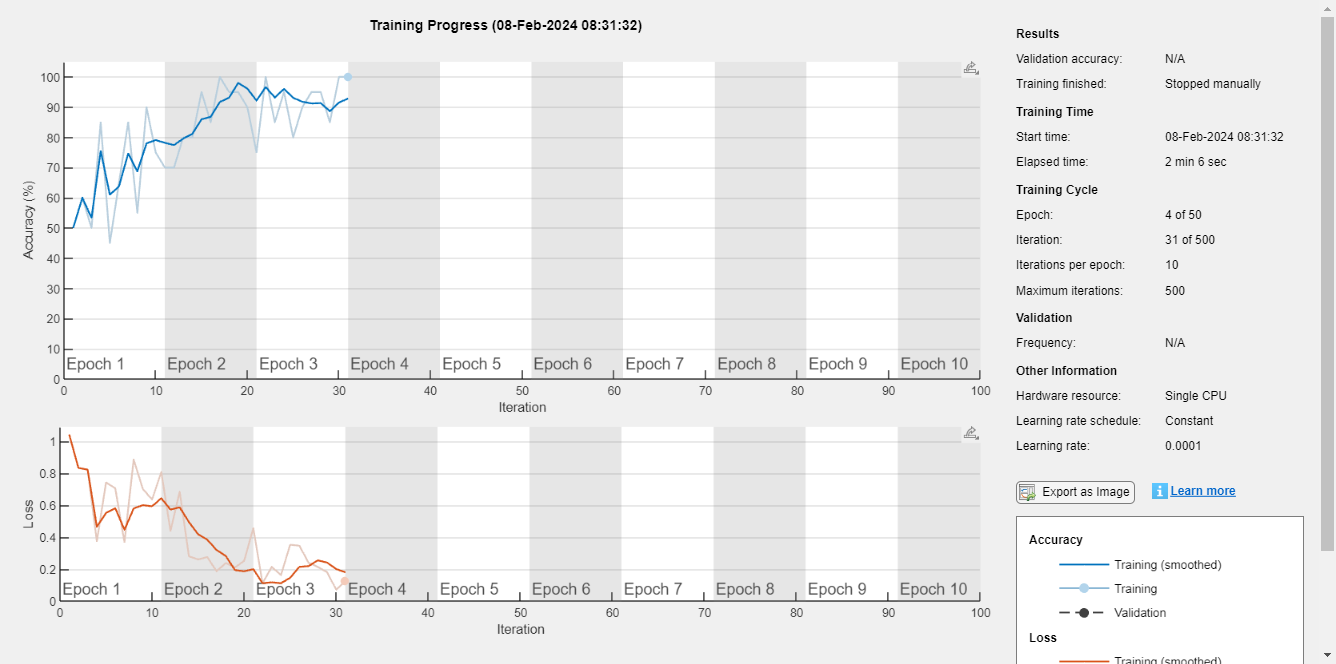

trainedNet = trainNetwork(trainImds,layers,opts);

Examine the performance of the network on the held-out test set.

ypred = trainedNet.classify(testImds);
cnnAccuracy = sum(ypred == testImds.Labels)/numel(testImds.Labels)*100

cnnAccuracy = 61.1765


figure
cchart = confusionchart(testImds.Labels,ypred);
cchart.Title = 'Confusion Chart for Deep CNN';
cchart.RowSummary = 'row-normalized';
cchart.ColumnSummary = 'column-normalized';

f1CNN = f1score(cchart.NormalizedValues);
disp(f1CNN)

                 F1   
               _______

    Crack       0.7201
    NoCrack    0.37488



# **Appendix — Supporting Functions**

function features = helperScatImages_mean(sn,x)
smat = featureMatrix(sn,x);
features = mean(smat,2:4);
features = features';
end
function F1scores = f1score(cchartVal)
N = sum(cchartVal,'all');
probT = sum(cchartVal)./N;
classProbEst = diag(cchartVal)./N;
Prec = classProbEst'./probT;
probC = [98/200 102/200];
Recall = classProbEst'./probC;
F1scores = harmmean([Prec ; Recall]);
F1scores = F1scores';
F1scores = table(F1scores,'VariableNames',{'F1'},...
    'RowNames', {'Crack','NoCrack'});
end

function labels = helperPCAClassifier(features,model)
% This function is only to support wavelet image scattering examples in 
% Wavelet Toolbox. It may change or be removed in a future release.
% model is a structure array with fields, M, mu, v, and Labels
% features is the matrix of test data which is Ns-by-L, Ns is the number of
% scattering paths and L is the number of test examples. Each column of
% features is a test example.

% Copyright 2018-2021 MathWorks

labelIdx = determineClass(features,model); 
labels = model.Labels(labelIdx); 
% Returns as column vector to agree with imageDatastore Labels
labels = labels(:);


%--------------------------------------------------------------------------
function labelIdx = determineClass(features,model)
% Determine number of classes
Nclasses = numel(model.Labels);
% Initialize error matrix
errMatrix = Inf(Nclasses,size(features,2));
for nc = 1:Nclasses
    % class centroid
    mu = model.mu{nc};
    u = model.U{nc};
    % 1-by-L
    errMatrix(nc,:) = projectionError(features,mu,u);
end
% Determine minimum along class dimension
[~,labelIdx] = min(errMatrix,[],1);   


%--------------------------------------------------------------------------
function totalerr = projectionError(features,mu,u)
    %
    Npc = size(u,2);
    L = size(features,2);
    % Subtract class mean: Ns-by-L minus Ns-by-1
    s = features-mu;
    % 1-by-L
    normSqX = sum(abs(s).^2,1)';
    err = Inf(Npc+1,L);
	err(1,:) = normSqX;
    err(2:end,:) = -abs(u'*s).^2;
    % 1-by-L
    totalerr = sqrt(sum(err,1));
end
end
end

function model = helperPCAModel(features,M,Labels)
% This function is only to support wavelet image scattering examples in
% Wavelet Toolbox. It may change or be removed in a future release.
% model = helperPCAModel(features,M,Labels)

% Copyright 2018-2021 MathWorks

% Initialize structure array to hold the affine model
model = struct('Dim',[],'mu',[],'U',[],'Labels',categorical([]),'S',[]);
model.Dim = M;
% Obtain the number of classes
LabelCategories = categories(Labels);
Nclasses = numel(categories(Labels));
for kk = 1:Nclasses
    Class = LabelCategories{kk};
    % Find indices corresponding to each class
    idxClass = Labels == Class;
    % Extract feature vectors for each class
    tmpFeatures = features(:,idxClass);
    % Determine the mean for each class
    model.mu{kk} = mean(tmpFeatures,2);
    [model.U{kk},model.S{kk}] = scatPCA(tmpFeatures);
    if size(model.U{kk},2) > M
        model.U{kk} = model.U{kk}(:,1:M);
        model.S{kk} = model.S{kk}(1:M);
        
    end
    model.Labels(kk) = Class;
end

    function [u,s,v] = scatPCA(x)
        % Calculate the principal components of x along the second dimension.
        [u,d] = eig(cov(x'));
        % Sort eigenvalues of covariance matrix in descending order
        [s,ind] = sort(diag(d),'descend');
        % sort eigenvector matrix accordingly
        u = u(:,ind);
    end
end